Importing data from excel spreadsheets to be used in simulation.

Thrust Curve Data:

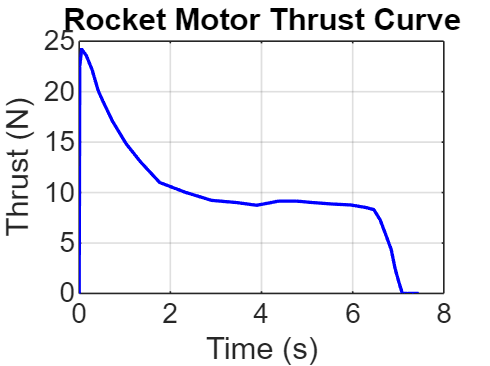

thrust_curve = readmatrix('ThrustCurve.xlsx');
thrustTime = thrust_curve(1:30,1);
thrustData = thrust_curve(1:30,2);

figure('Name', 'Thrust Curve');
plot(thrustTime, thrustData, 'b-', 'LineWidth', 1);
xlabel('Time (s)');
ylabel('Thrust (N)');
title('Rocket Motor Thrust Curve');
grid on;

Aerodynamic Forces & Moments Coefficients

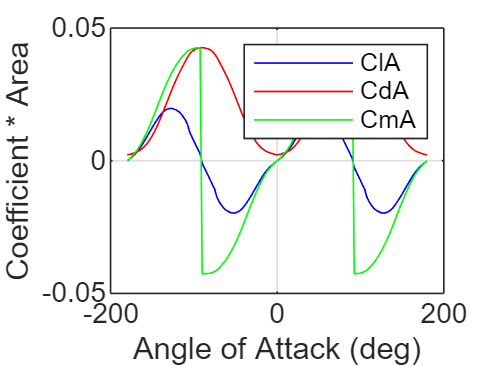

ansys_data = readmatrix('Ansys_Aerodynamic_Forces_Moments.xlsx');

%Extract only the data for 0-90 degrees AOA
aeroData.AOA = ansys_data(3:39,1);  %Angle of Attack (0-90 degrees)
aeroData.CdA = ansys_data(3:39,15); %Coefficient of Drag * Reference Area
aeroData.ClA = ansys_data(3:39,17); %Coefficient of Lift * Reference Area
aeroData.CnA = ansys_data(3:39,19); %Coefficient of Normal Force * Reference Area
aeroData.CmA = ansys_data(3:39,24); %Coefficient of Static Moment * Reference Area
aeroData.CP = ansys_data(3:39,23);  %Location of Center of Pressure
aeroData.damp = ansys_data(3:39, 26); %Damping Moment Coefficient

%Create data for [-90,0] AOA using symmetric assumptions
AOA_neg = -flip(aeroData.AOA(2:end));
CdA_neg =  flip(aeroData.CdA(2:end));      
ClA_neg = -flip(aeroData.ClA(2:end));       
CnA_neg =  flip(aeroData.CnA(2:end));       
CmA_neg = -flip(aeroData.CmA(2:end));       
CP_neg  =  flip(aeroData.CP(2:end));
damp_neg  =  flip(aeroData.damp(2:end));

%Create data for 0-180 degrees:
AOA_mirror = 180 - flip(aeroData.AOA(1:end-1));  % exclude 90 to avoid duplicate
CdA_mirror = flip(aeroData.CdA(1:end-1));
ClA_mirror = -flip(aeroData.ClA(1:end-1));
CnA_mirror = flip(aeroData.CnA(1:end-1));
CmA_mirror = -flip(aeroData.CmA(1:end-1));
CP_mirror  = flip(aeroData.CP(1:end-1));
damp_mirror  = flip(aeroData.damp(1:end-1));

%Create data for [-180,-90] AOA
AOA_mirror_neg = -AOA_mirror;
CdA_mirror_neg = CdA_mirror;
ClA_mirror_neg = -ClA_mirror;
CnA_mirror_neg = CnA_mirror;
CmA_mirror_neg = -CmA_mirror;
CP_mirror_neg  = CP_mirror;
damp_mirror_neg  = damp_mirror;

%Combine to get full range: [-180,180]
aeroData.AOA = [AOA_mirror_neg; AOA_neg; aeroData.AOA; AOA_mirror];
aeroData.CdA = [CdA_mirror_neg; CdA_neg; aeroData.CdA; CdA_mirror];
aeroData.ClA = [ClA_mirror_neg; ClA_neg; aeroData.ClA; ClA_mirror];
aeroData.CnA = [CnA_mirror_neg; CnA_neg; aeroData.CnA; CnA_mirror];
aeroData.CmA = [CmA_mirror_neg; CmA_neg; aeroData.CmA; CmA_mirror];
aeroData.CP  = [CP_mirror_neg;  CP_neg;  aeroData.CP;  CP_mirror];
aeroData.damp = [damp_mirror_neg; damp_neg; aeroData.damp; damp_mirror];

%Sort everything in the proper [-180,180 order]
[aeroData.AOA, sortIdx] = sort(aeroData.AOA);
aeroData.CdA = aeroData.CdA(sortIdx);
aeroData.ClA = aeroData.ClA(sortIdx);
aeroData.CnA = aeroData.CnA(sortIdx);
aeroData.CmA = aeroData.CmA(sortIdx);
aeroData.CP  = aeroData.CP(sortIdx);
aeroData.damp = aeroData.damp(sortIdx);



figure;
plot(aeroData.AOA, aeroData.ClA, 'b', ...
     aeroData.AOA, aeroData.CdA, 'r', ...
     aeroData.AOA, aeroData.CmA, 'g');
xlabel('Angle of Attack (deg)');
ylabel('Coefficient * Area');
legend('ClA', 'CdA', 'CmA');
grid on;

Create Buses for the Structs

Simulink.Bus.createObject(aeroData);